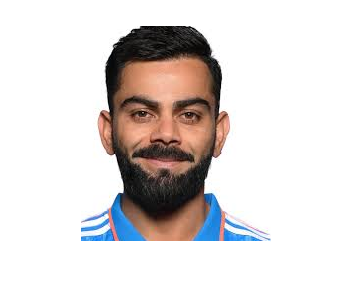

trainDir = 'faces_dataset/';
imageFiles = dir(fullfile(trainDir, '*.jpg'));
numImages = length(imageFiles);
imageSize = [100, 100];
X = zeros(prod(imageSize), numImages);
labels = strings(1, numImages);

for i = 1:numImages
    img = imread(fullfile(trainDir, imageFiles(i).name));
    img = rgb2gray(imresize(img, imageSize));
    X(:, i) = img(:); 
    labels(i) = extractBefore(imageFiles(i).name, '_'); 
end

meanFace = mean(X, 2);
X_centered = X - meanFace;
[coeff, ~, ~] = pca(X_centered', 'NumComponents', 50);

knnModel = fitcknn(X_centered' * coeff, labels);

queryImg = imread('unknown_face.jpg');
imshow(queryImg)

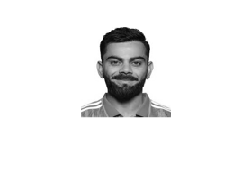

queryImg = rgb2gray(imresize(queryImg, imageSize));
imshow(queryImg)

queryVec = double(queryImg(:)) - meanFace;
queryFeature = queryVec' * coeff;

predictedLabel = predict(knnModel, queryFeature);

disp(['Identified as: ', predictedLabel]);

    {'Identified as: '}    {'Virat'}

